# **Práctica 1: Análisis de la Respuesta Temporal de un Sistema de Control Digital**

Las practicas de la asignatura Control con Computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. La sesión P3 se dedica al diseño de controladores PID.

**OBJETIVO: Análisis de la respuesta temporal de un sistema de control digital para diferentes periodos de muestreo. Análisis de la precisión y de la estabilidad.**

**En esta sesión el estudiante ha de:**

- **Familiarizarse con el sistema: con la planta de tiempo continuo y con el uso del computador como generador de señales, osciloscopio y controlador digital.**

- **Evaluar las prestaciones (precisión y estabilidad) del sistema en función del periodo de muestreo.**

% Alternar entre los datos del experimento y los del directorio Resultados
usarDatosExperimentales = true;

# Ejercicio 1: Respuesta del sistema en lazo abierto para la señal del tacómetro.

Abrir y ejecutar el modelo P1_Ex1.slx. Comprobar que es la respuesta típica de un sistema de primer orden y cómo varía la ganancia estática si aplicamos al motor el freno magnético. Identificar la constante de tiempo $\tau_0$ y la ganancia estática $K_0$ para una entrada escalón de 1V. 

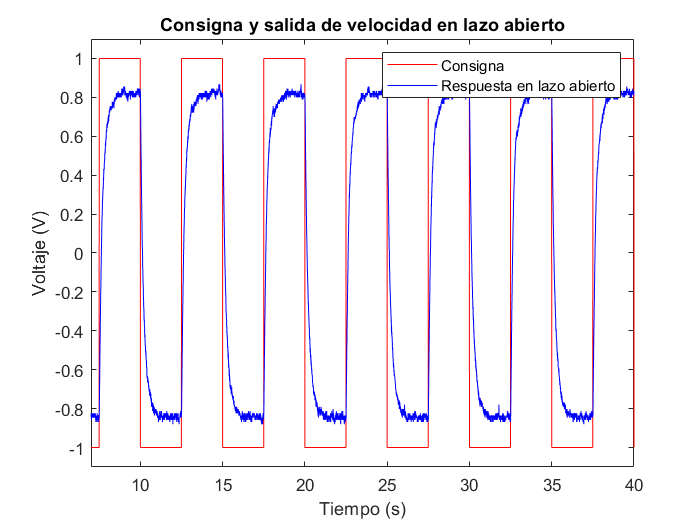

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

% Si el Arduino está conectado a alguna planta y se 
% desea hacer el experimento, descomenta los siguientes comandos.

% open P1_Ex1.slx
% run P1_Ex1.slx

% Dibujar la respuesta del motor
if usarDatosExperimentales
    % Usar Simulink
    addpath([pwd filesep 'Ejercicio1']);
    open P1_Ex1.slx;
    run P1_Ex1.slx;
else
    FileName   = 'OpenLoopResponse.mat';
    FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex1';
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
xlim([7 40]); ylim([-1.1 1.1]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');

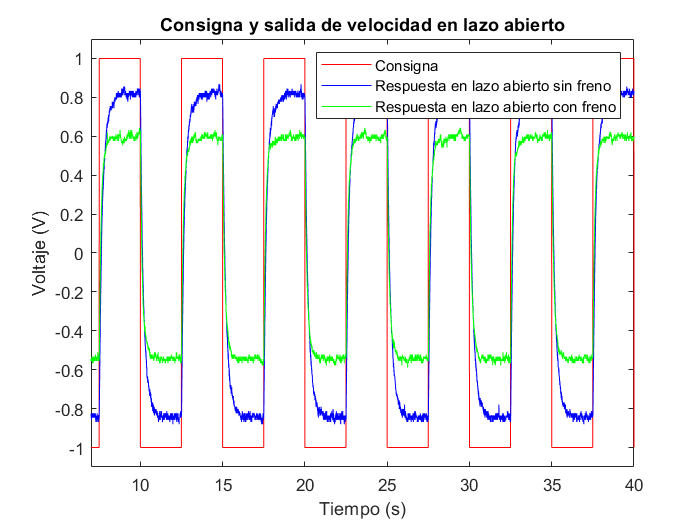

title('Vin y salida de velocidad en lazo abierto');
legend('Vin','Respuesta en lazo abierto');


% Aplicación del freno en lazo abierto
FileName   = 'OpenLoopBrake.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex1';
File       = fullfile(FolderName, FileName);
load(File);


figure
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopResponse.time,[OpenLoopResponse.signals.values(:,2,:)],'b')
plot(OpenLoopBrake.time,[OpenLoopBrake.signals.values(:,2,:)],'g')
xlim([7 40]); ylim([-1.1 1.1]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');

title('Vin y salida de velocidad en lazo abierto');
legend('Vin','Respuesta en lazo abierto sin freno','Respuesta en lazo abierto con freno');

# Ejercicio 2: Respuesta del sistema en lazo cerrado con realimentación de velocidad.

Abrir y ejecutar el modelo P1_Ex2.slx. Comprobar cómo varía el error en estado estacionario para Kp= 1, 2, 5 y 10, cambiando el bloque "Controlador Proporcional"

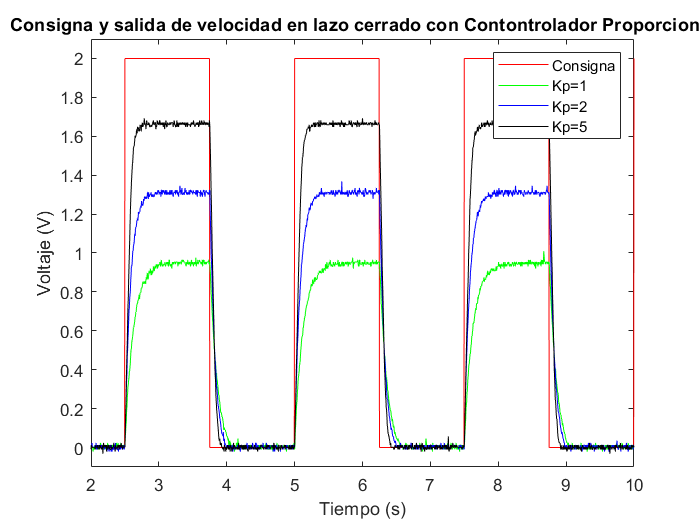

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

% Si el Arduino está conectado a alguna planta y se 
% desea hacer el experimento, descomenta los siguientes comandos.

% open P1_Ex2.slx

% Cargar variables
FileName   = 'Kp1.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex2';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Kp2.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex2';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Kp5.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex2';
File       = fullfile(FolderName, FileName);
load(File);


% señales de salida
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,1,:)],'k')
xlim([2 10]); ylim([-0.1 2.1]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=5');

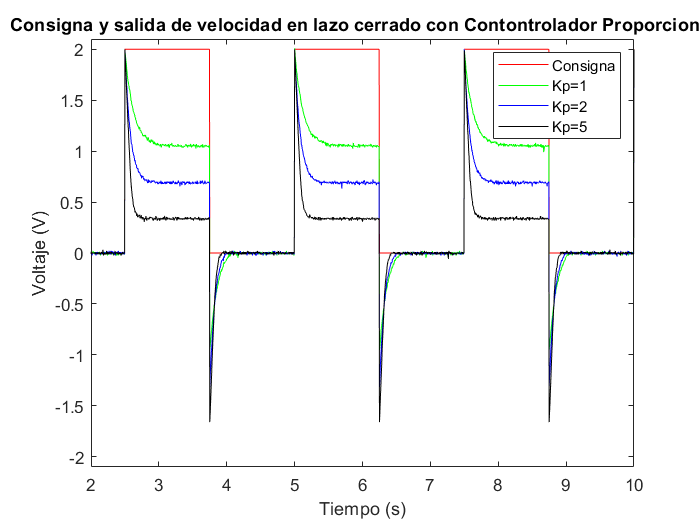


% señales de error
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp5.time, [Kp5.signals.values(:,2,:)],'k')
xlim([2 10]); ylim([-2.1 2.1]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=5');

# Ejercicio 3: Evaluación experimental de las prestaciones del sistema en lazo cerrado con realimentación de velocidad. 

Abirir y ejecutar el modelo P1_Ex3.slx. Evaluar cómo varía la precisión y la estabilidad del sistema para diferentes periodos de muestreo.

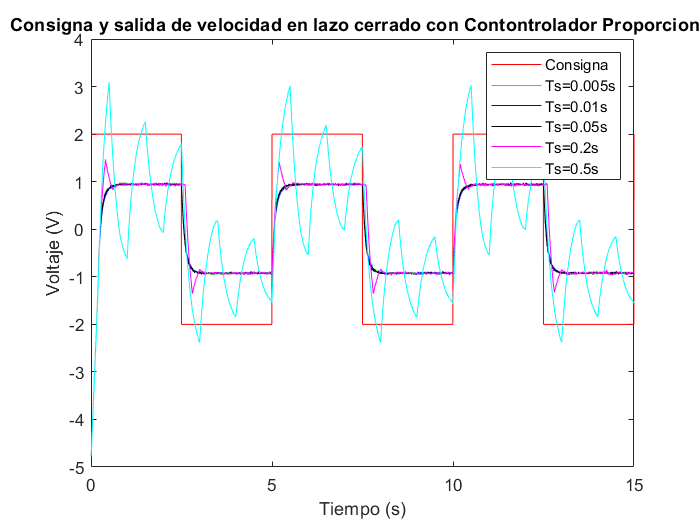

% Inicialización de variables
Tg= 0.005; % Tiempo de graficación [seg]
Ts=0.01; % Tiempo de muestreo
Vmax=5; % [V]
Vmin=-5; % [V]

% Si el Arduino está conectado a alguna planta y se 
% desea hacer el experimento, descomenta los siguientes comandos.

%open P1_Ex3.slx


% Cargar variables
FileName   = 'Ts5ms.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex3';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts10ms.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex3';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts50ms.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex3';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts02s.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex3';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts05s.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex3';
File       = fullfile(FolderName, FileName);
load(File);

% salida
figure(1)
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,3,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,3,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,3,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,3,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,3,:)],'c')
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

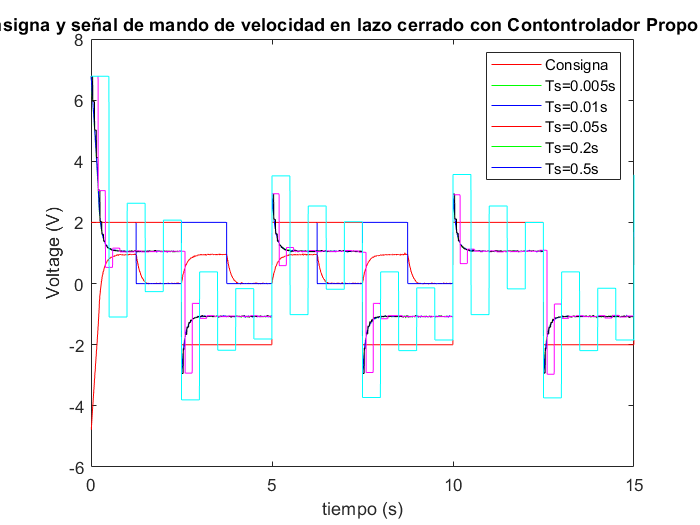


% error
figure(2)
plot(Ts5ms.time,[Ts5ms.signals.values(:,2,:)],'r')
hold all
plot(Ts5ms.time, [Ts5ms.signals.values(:,1,:)],'g')
plot(Ts10ms.time, [Ts10ms.signals.values(:,1,:)],'b')
plot(Ts50ms.time, [Ts50ms.signals.values(:,1,:)],'k')
plot(Ts02s.time, [Ts02s.signals.values(:,1,:)],'m')
plot(Ts05s.time, [Ts05s.signals.values(:,1,:)],'c')
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y señal de mando de velocidad en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.2s','Ts=0.5s')

# Ejercicio 4: Respuesta del sistema en lazo abierto para la señal del potenciómetro.

Abrir y ejecutar el modelo P1_Ex4.slx. Comprobar que es la respuesta típica de un sistema de tipo 1. 

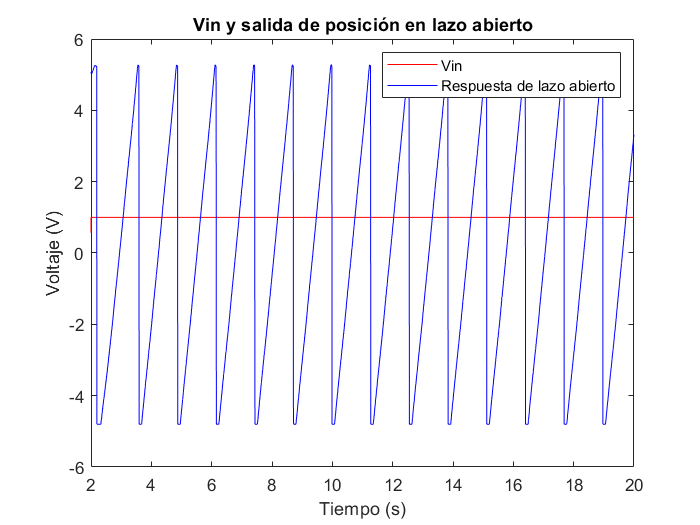

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

% Si el Arduino está conectado a alguna planta y se 
% desea hacer el experimento, descomenta los siguientes comandos.

% open P1_Ex4.slx
% run P1_Ex4.slx

% Cargar respuesta lazo abierto
FileName   = 'OpenLoopPosition.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex4';
File       = fullfile(FolderName, FileName);
load(File);

% salida
figure
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,1,:)],'r')
hold on
plot(OpenLoopPosition.time,[OpenLoopPosition.signals.values(:,2,:)],'b')
xlim([2 20]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Vin y salida de posición en lazo abierto');
legend('Vin','Respuesta de lazo abierto');

# Ejercicio 5: Respuesta del sistema en lazo cerrado con realimentación de posición.

Abrir y ejecutar el modelo P1_Ex5.slx. Comprobar cómo varía el error en estado estacionario para Kp= 1, 2 y 3, cambiando el bloque "Controlador Proporcional".

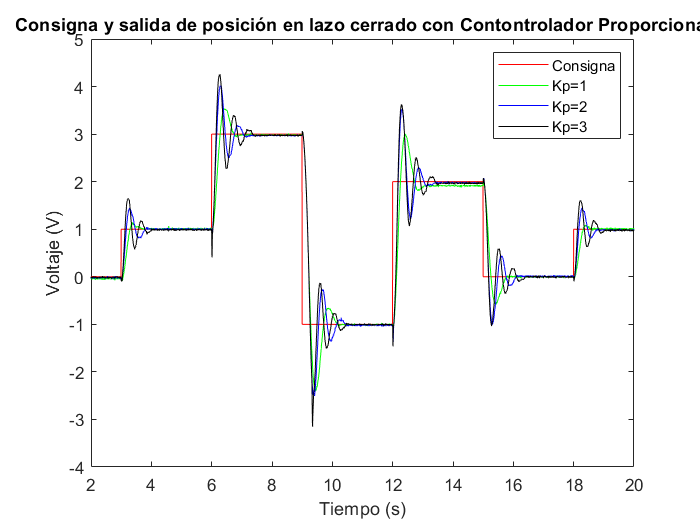

% Inicialización de variables
Tg=0.005; % Tiempo de graficación [seg]
Vmax=5; % [V]
Vmin=-5; % [V]

% Si el Arduino está conectado a alguna planta y se 
% desea hacer el experimento, descomenta los siguientes comandos.

% open P1_Ex5.slx

% Cargar variables
FileName   = 'Kp1.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex5';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Kp2.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex5';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Kp3.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex5';
File       = fullfile(FolderName, FileName);
load(File);


% salida
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,1,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,1,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,1,:)],'k')
xlim([2 20]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=3');

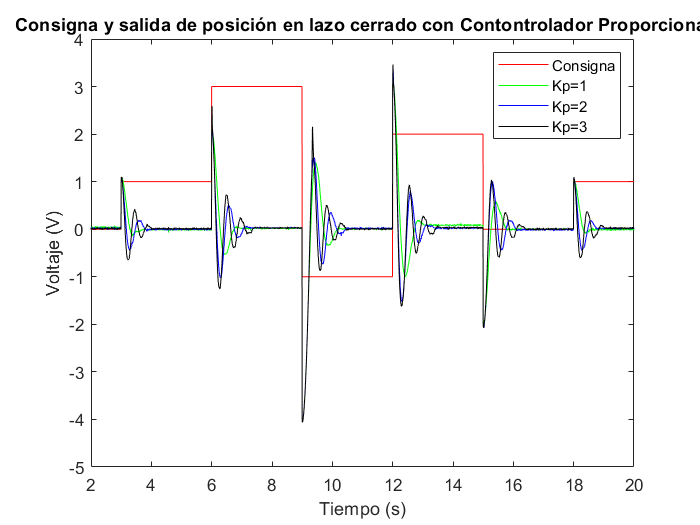


% error
figure
plot(Kp1.time,[Kp1.signals.values(:,3,:)],'r') 
hold all
plot(Kp1.time, [Kp1.signals.values(:,2,:)],'g')
plot(Kp2.time, [Kp2.signals.values(:,2,:)],'b')
plot(Kp3.time, [Kp3.signals.values(:,2,:)],'k')
xlim([2 20]);
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Consigna y salida de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Kp=1','Kp=2','Kp=3');

# Ejercicio 6: Evaluación experimental de las prestaciones del sistema en lazo cerrado con realimentación de posición. 

Abirir y ejecutar el modelo P1_Ex6.slx. Evaluar cómo varía la precisión y la estabilidad del sistema para diferentes periodos de muestreo.

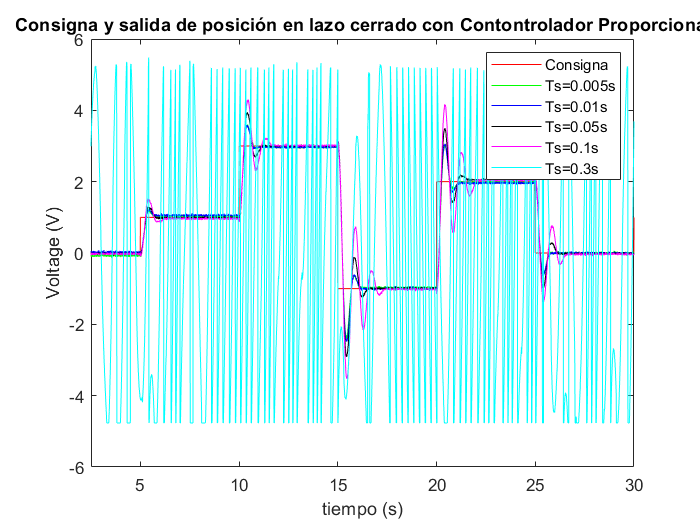

% Inicialización de variables
Tg= 0.005; % Tiempo de graficación [seg]
Ts=0.01; % Tiempo de muestreo
Vmax=5; % [V]
Vmin=-5; % [V]

% Si el Arduino está conectado a alguna planta y se 
% desea hacer el experimento, descomenta los siguientes comandos.

% open P1_Ex6.slx

% Cargar variables
FileName   = 'Ts005.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex6';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts01.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex6';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts05.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex6';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts1.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex6';
File       = fullfile(FolderName, FileName);
load(File);

FileName   = 'Ts3.mat';
FolderName = 'C:\Users\Eneko Lerma\Desktop\IntroSimulinkArduino\LiveScript\Variables\Practica1\Ex6';
File       = fullfile(FolderName, FileName);
load(File);

% salida
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all
plot(Ts005.time, [Ts005.signals.values(:,3,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,3,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,3,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,3,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,3,:)],'c')
xlim([2.5 30]);
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y salida de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')

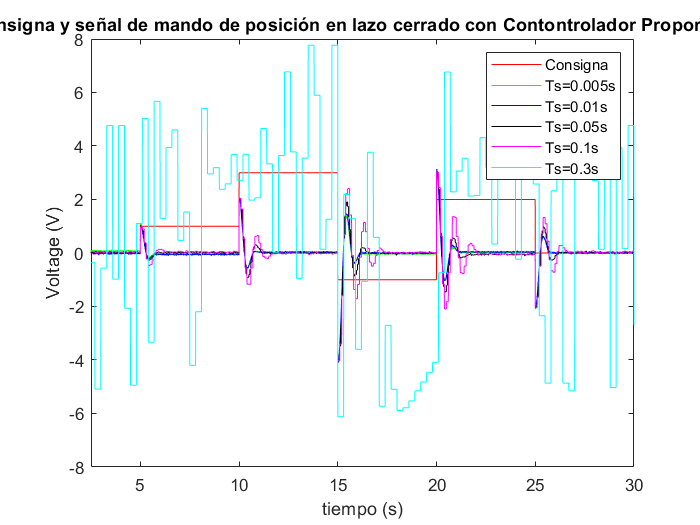


% error
figure
plot(Ts005.time, [Ts005.signals.values(:,2,:)],'r')
hold all
plot(Ts005.time, [Ts005.signals.values(:,1,:)],'g')
plot(Ts01.time, [Ts01.signals.values(:,1,:)],'b')
plot(Ts05.time, [Ts05.signals.values(:,1,:)],'k')
plot(Ts1.time, [Ts1.signals.values(:,1,:)],'m')
plot(Ts3.time, [Ts3.signals.values(:,1,:)],'c')
xlim([2.5 30]);
xlabel('tiempo (s)');
ylabel('Voltage (V)');
title('Consigna y señal de mando de posición en lazo cerrado con Contontrolador Proporcional');
legend('Consigna','Ts=0.005s','Ts=0.01s','Ts=0.05s','Ts=0.1s','Ts=0.3s')